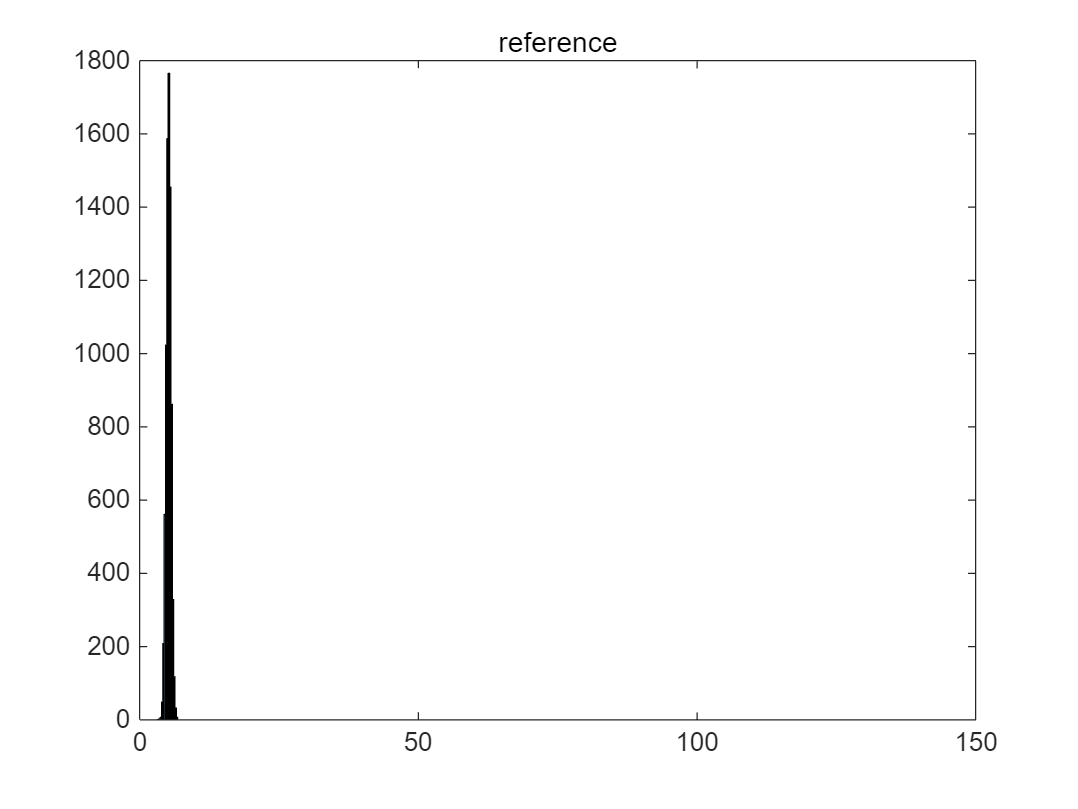

reference done


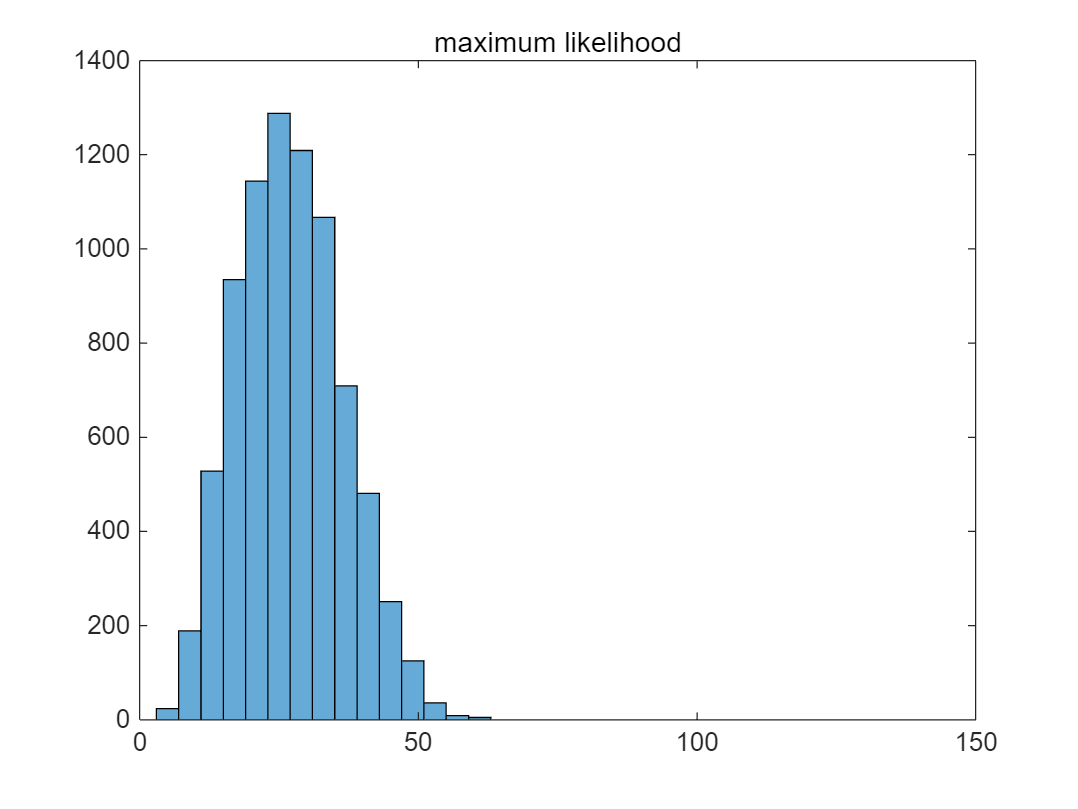

maximum likelihood done


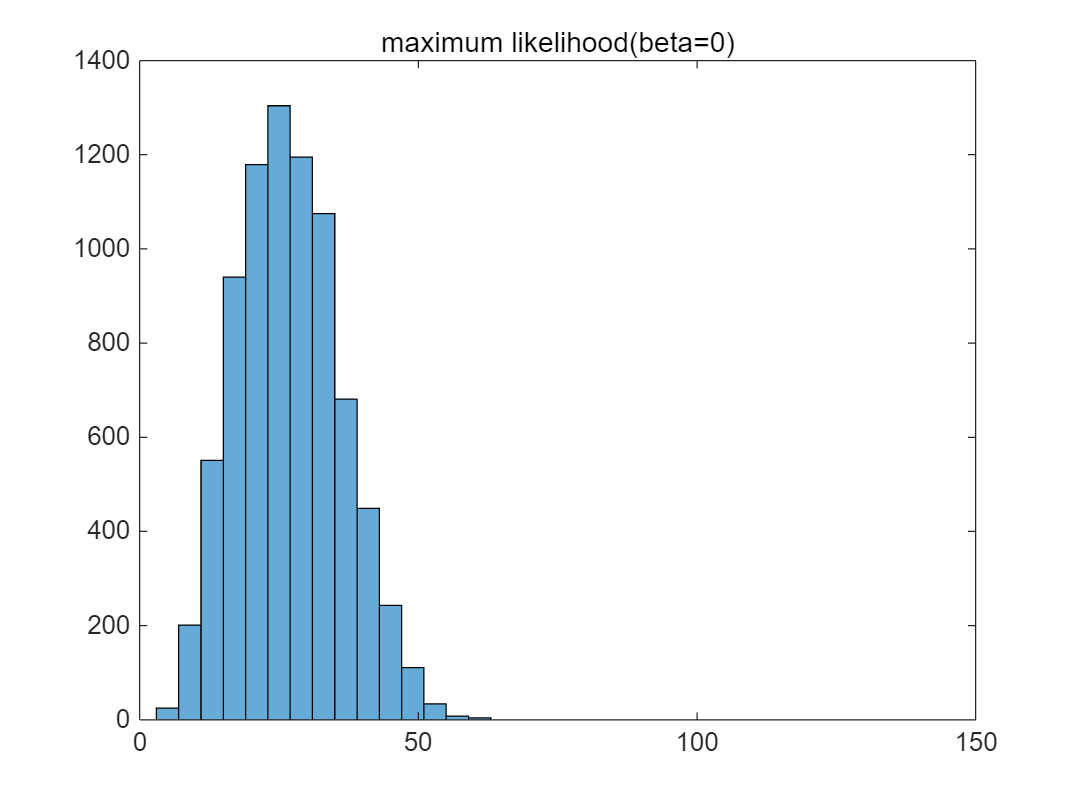

maximum likelihood(beta=0) done


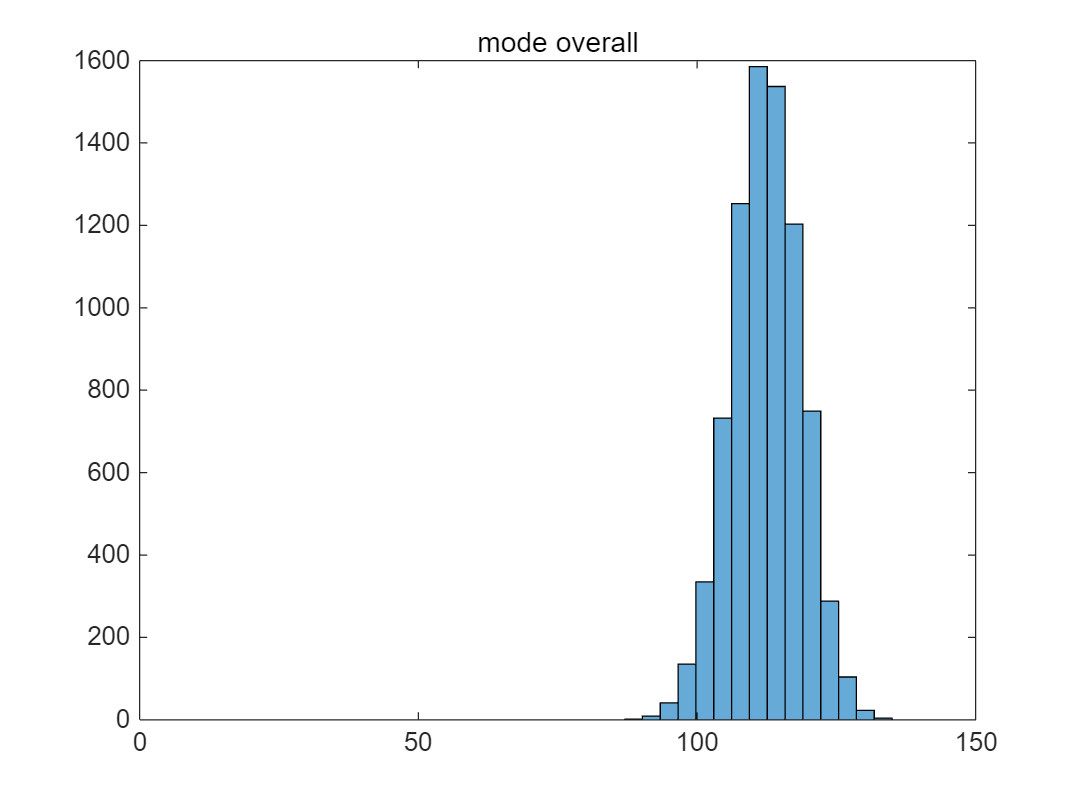

mode overall done


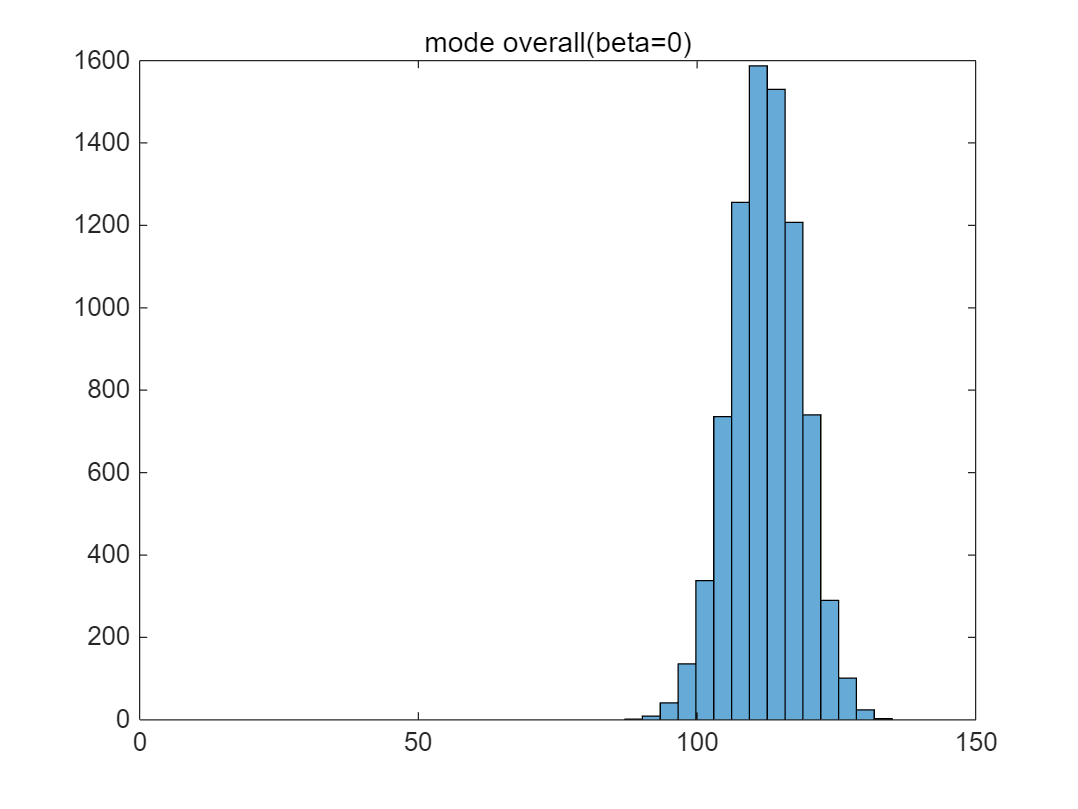

mode overall(beta=0) done


%% default setting

% first dimension: default; second dimension: the power of the parameter
params_ref=struct( ...
    'eta',{12.5}, ... % 12.5
    'beta',{0}, ... % should be 0.11? beta=0 for much easier analytical solving
    'epsilon',{83}, ...
    'X_c',{176}, ...
    'X_d',{150}, ... % artificial.. should be checked
    'kappa',{0});

params_ml=struct( ...
    'eta',{0.314}, ... 
    'beta',{0.121}, ... 
    'epsilon',{223.651}, ...
    'X_c',{185.273}, ...
    'X_d',{150}, ... % artificial.. should be checked
    'kappa',{4.146*0.121});

params_ml_0=struct( ...
    'eta',{0.314}, ... 
    'beta',{0}, ... 
    'epsilon',{223.651}, ...
    'X_c',{185.273}, ...
    'X_d',{150}, ... % artificial.. should be checked
    'kappa',{0});

params_mo=struct( ...
    'eta',{0.0284}, ...
    'beta',{0.000572}, ... 
    'epsilon',{1.983}, ...
    'X_c',{185.273}, ...
    'X_d',{150}, ... % artificial.. should be checked
    'kappa',{87.402*0.000572});

params_mo_0=struct( ...
    'eta',{0.0284}, ...
    'beta',{0}, ... 
    'epsilon',{1.983}, ...
    'X_c',{185.273}, ...
    'X_d',{150}, ... % artificial.. should be checked
    'kappa',{0});

params_cells={params_ref,params_ml,params_ml_0,params_mo,params_mo_0};
names_cells={"reference","maximum likelihood","maximum likelihood(beta=0)",...
    "mode overall","mode overall(beta=0)"};
%%

for i=1:length(params_cells)
% function [X_paths,t]=SR_asimu(param_struct,X0,M,EndTime,dt)
[X_paths_yeast,t]=SR_simu2(params_cells{i},0.001,8000,200,0.01);     % for avoiding /0, X0!=0
% figure
% plot(t, X_paths_yeast)
% hold on
% plot(t,params_ml.X_c.*ones(length(t),1),'LineWidth',1.5,'Color','r')
% xlabel('T/day')
% ylabel('X')
% title(names_cells{i})
% function [DeathTime,DiseaseTime,t]=SR_time(X,param_struct,t)

[death_time,~,t]=SR_time(X_paths_yeast,params_cells{i},t);
figure 
histogram(death_time,15)
xlim([0,150])
title(names_cells{i})
fprintf("%s done\n",names_cells{i})
clear("disease_time","death_time")
end






%%
function [X_paths,t]=SR_simu2(param_struct,X0,M,EndTime,dt)
% param_struct must contain element "eta","beta","kappa","epsilon"
t=0:dt:EndTime;
N=EndTime/dt;
X_paths = X0.*ones(M, N+1);
rng(666)
for n = 1:N
    t_seq=t(n)*ones(M,1);
    mu = param_struct.eta .* t_seq- param_struct.beta .* (X_paths(:, n) ./ (X_paths(:, n) + param_struct.kappa));
    dW = sqrt(dt) .* randn(M,1);
    X_paths(:,n+1) = X_paths(:,n) + mu*dt+ sqrt(2*param_struct.epsilon).*dW;
    X_paths(X_paths(:,n+1)<0,n+1)=0.001;
end

end




function [DeathTime,DiseaseTime,t]=SR_time(X,param_struct,t)
% param_struct must contain element "X_c","X_d"
n_sample=length(X(:,1));
n_step=length(X(1,:));
DeathTime=zeros(n_sample,1);
DiseaseTime=zeros(n_sample,1);
X_temp=X;
% for first-crossing
for m = 1:n_sample
    q=0;    % a switch for disease
    for n = 1:n_step
        if X_temp(m,n)> param_struct.X_d && q==0
            DiseaseTime(m)=t(n);
            q=1;
        end
        if X_temp(m,n)> param_struct.X_c
            DeathTime(m)=t(n);
            break
        end
    end
end
end

